# Signal Smoothing

This example shows how to use moving average filters and resampling to isolate the effect of periodic components of the time of day on hourly temperature readings, as well as remove unwanted line noise from an open-loop voltage measurement. The example also shows how to smooth the levels of a clock signal while preserving the edges by using a median filter. The example also shows how to use a Hampel filter to remove large outliers.

## Motivation

Smoothing is how we discover important patterns in our data while leaving out things that are unimportant (i.e. noise). We use filtering to perform this smoothing. The goal of smoothing is to produce slow changes in value so that it's easier to see trends in our data.

Sometimes when you examine input data you may wish to smooth the data in order to see a trend in the signal. In our example we have a set of temperature readings in Celsius taken every hour at Logan Airport in Boston for the entire month of January, 2011.

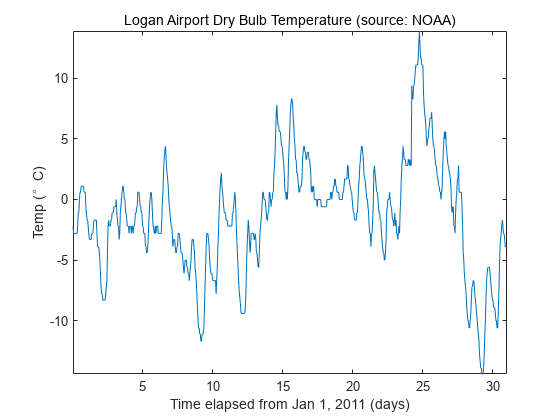

load bostemp
days = (1:31*24)/24;
plot(days, tempC)
axis tight
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

Note that we can visually see the effect that the time of day has upon the temperature readings. If you are only interested in the daily temperature variation over the month, the hourly fluctuations only contribute noise, which can make the daily variations difficult to discern. To remove the effect of the time of day, we would now like to smooth our data by using a moving average filter.

## A Moving Average Filter

In its simplest form, a moving average filter of length N takes the average of every N consecutive samples of the waveform.

To apply a moving average filter to each data point, we construct our coefficients of our filter so that each point is equally weighted and contributes 1/24 to the total average. This gives us the average temperature over each 24 hour period.

hoursPerDay = 24;
coeff24hMA = ones(1, hoursPerDay)/hoursPerDay;

avg24hTempC = filter(coeff24hMA, 1, tempC);
plot(days,[tempC avg24hTempC])
legend('Hourly Temp','24 Hour Average (delayed)','location','best')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

## Filter Delay

Note that the filtered output is delayed by about twelve hours. This is due to the fact that our moving average filter has a delay.

Any symmetric filter of length N will have a delay of (N-1)/2 samples. We can account for this delay manually.

fDelay = (length(coeff24hMA)-1)/2;
plot(days,tempC, ...
     days-fDelay/24,avg24hTempC)
axis tight
legend('Hourly Temp','24 Hour Average','location','best')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

## Extracting Average Differences

Alternatively, we can also use the moving average filter to obtain a better estimate of how the time of day affects the overall temperature. To do this, first, subtract the smoothed data from the hourly temperature measurements. Then, segment the differenced data into days and take the average over all 31 days in the month.

figure
deltaTempC = tempC - avg24hTempC;
deltaTempC = reshape(deltaTempC, 24, 31).';

plot(1:24, mean(deltaTempC))
axis tight
title('Mean temperature differential from 24 hour average')
xlabel('Hour of day (since midnight)')
ylabel('Temperature difference (\circC)')

## Extracting Peak Envelope

Sometimes we would also like to have a smoothly varying estimate of how the highs and lows of our temperature signal change daily. To do this we can use the `envelope` function to connect extreme highs and lows detected over a subset of the 24 hour period. In this example, we ensure there are at least 16 hours between each extreme high and extreme low. We can also get a sense of how the highs and lows are trending by taking the average between the two extremes.

[envHigh, envLow] = envelope(tempC,16,'peak');
envMean = (envHigh+envLow)/2;

plot(days,tempC, ...
     days,envHigh, ...
     days,envMean, ...
     days,envLow)
   
axis tight
legend('Hourly Temp','High','Mean','Low','location','best')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

## Weighted Moving Average Filters

Other kinds of moving average filters do not weight each sample equally.

Another common filter follows the binomial expansion of ${\left\lbrack 1/2,1/2\right\rbrack }^n$. This type of filter approximates a normal curve for large values of n. It is useful for filtering out high frequency noise for small n. To find the coefficients for the binomial filter, convolve $\left\lbrack 1/2,1/2\right\rbrack$ with itself and then iteratively convolve the output with $\left\lbrack 1/2,1/2\right\rbrack$ a prescribed number of times. In this example, use five total iterations.

h = [1/2 1/2];
binomialCoeff = conv(h,h);
for n = 1:4
    binomialCoeff = conv(binomialCoeff,h);
end

figure
fDelay = (length(binomialCoeff)-1)/2;
binomialMA = filter(binomialCoeff, 1, tempC);
plot(days,tempC, ...
     days-fDelay/24,binomialMA)
axis tight
legend('Hourly Temp','Binomial Weighted Average','location','best')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

Another filter somewhat similar to the Gaussian expansion filter is the exponential moving average filter. This type of weighted moving average filter is easy to construct and does not require a large window size.

You adjust an exponentially weighted moving average filter by an alpha parameter between zero and one. A higher value of alpha will have less smoothing.

alpha = 0.45;
exponentialMA = filter(alpha, [1 alpha-1], tempC);
plot(days,tempC, ...
     days-fDelay/24,binomialMA, ...
     days-1/24,exponentialMA)

axis tight
legend('Hourly Temp', ...
       'Binomial Weighted Average', ...
       'Exponential Weighted Average','location','best')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')

Zoom in on the readings for one day.

axis([3 4 -5 2])

## Savitzky-Golay Filters

You'll note that by smoothing the data, the extreme values were somewhat clipped.

To track the signal a little more closely, you can use a weighted moving average filter that attempts to fit a polynomial of a specified order over a specified number of samples in a least-squares sense.

As a convenience, you can use the function `sgolayfilt` to implement a Savitzky-Golay smoothing filter. To use `sgolayfilt`, you specify an odd-length segment of the data and a polynomial order strictly less than the segment length. The `sgolayfilt` function internally computes the smoothing polynomial coefficients, performs delay alignment, and takes care of transient effects at the start and end of the data record.

cubicMA   = sgolayfilt(tempC, 3, 7);
quarticMA = sgolayfilt(tempC, 4, 7);
quinticMA = sgolayfilt(tempC, 5, 9);
plot(days,[tempC cubicMA quarticMA quinticMA])
legend('Hourly Temp','Cubic-Weighted MA', 'Quartic-Weighted MA', ...
       'Quintic-Weighted MA','location','southeast')
ylabel('Temp (\circC)')
xlabel('Time elapsed from Jan 1, 2011 (days)')
title('Logan Airport Dry Bulb Temperature (source: NOAA)')
axis([3 5 -5 2])

## Resampling

Sometimes it is beneficial to resample a signal in order to properly apply a moving average.

In our next example, we sampled the open-loop voltage across the input of an analog instrument in the presence of interference from 60 Hz AC power line noise. We sampled the voltage with a 1 kHz sampling rate.

load openloop60hertz
fs = 1000;
t = (0:numel(openLoopVoltage)-1) / fs;
plot(t,openLoopVoltage)
ylabel('Voltage (V)')
xlabel('Time (s)')
title('Open-loop Voltage Measurement')

Let's attempt to remove the effect of the line noise by using a moving average filter. 

If you construct a uniformly weighted moving average filter, it will remove any component that is periodic with respect to the duration of the filter.

There are roughly 1000 / 60 = 16.667 samples in a complete cycle of 60 Hz when sampled at 1000 Hz. Let's attempt to "round up" and use a 17-point filter. This will give us maximal filtering at a fundamental frequency of 1000 Hz / 17 = 58.82 Hz. 

plot(t,sgolayfilt(openLoopVoltage,1,17))
ylabel('Voltage (V)')
xlabel('Time (s)')
title('Open-loop Voltage Measurement')
legend('Moving average filter operating at 58.82 Hz', ...
       'Location','southeast')

Note that while the voltage is significantly smoothed, it still contains a small 60 Hz ripple.

We can significantly reduce the ripple if we resample the signal so that we capture a complete full cycle of the 60 Hz signal by our moving average filter.

If we resample the signal at 17 * 60 Hz = 1020 Hz, we can use our 17 point moving average filter to remove the 60 Hz line noise.

fsResamp = 1020;
vResamp = resample(openLoopVoltage, fsResamp, fs);
tResamp = (0:numel(vResamp)-1) / fsResamp;
vAvgResamp = sgolayfilt(vResamp,1,17);
plot(tResamp,vAvgResamp)
ylabel('Voltage (V)')
xlabel('Time (s)')
title('Open-loop Voltage Measurement')
legend('Moving average filter operating at 60 Hz', ...
    'Location','southeast')

## Median Filter

Moving average, weighted moving average, and Savitzky-Golay filters smooth all of the data they filter. This, however, may not always be what is wanted. For example, what if our data is taken from a clock signal and has sharp edges that we do not wish to smooth? The filters discussed so far do not work so well:

load clockex

yMovingAverage = conv(x,ones(5,1)/5,'same');
ySavitzkyGolay = sgolayfilt(x,3,5);
plot(t,x, ...
     t,yMovingAverage, ...
     t,ySavitzkyGolay)

legend('original signal','moving average','Savitzky-Golay')

The moving average and Savitzky-Golay filters respectively under-correct and over-correct near the edges of the clock signal.

A simple way to preserve the edges, but still smooth the levels is to use a median filter: 

yMedFilt = medfilt1(x,5,'truncate');
plot(t,x, ...
     t,yMedFilt)
legend('original signal','median filter')

## Outlier Removal via Hampel Filter

Many filters are sensitive to outliers. A filter which is closely related to the median filter is the Hampel filter. This filter helps to remove outliers from a signal without overly smoothing the data.

To see this, load an audio recording of a train whistle and add some artificial noise spikes:

load train
y(1:400:end) = 2.1;
plot(y)

Since each spike we introduced has a duration of just one sample, we can use a median filter of just three elements to remove the spikes.

hold on
plot(medfilt1(y,3))
hold off
legend('original signal','filtered signal')

The filter removed the spikes, but it also removed a large number of data points of the original signal. A Hampel filter works similar to a median filter, however it replaces just the values which are equivalent to a few standard deviations away from the local median value.

hampel(y,13)
legend('location','best')

Only the outliers are removed from the original signal.

## Further Reading

For more information on filtering and resampling see the Signal Processing Toolbox.

Reference: Kendall, Maurice G., Alan Stuart, and J. Keith Ord. *The Advanced Theory of Statistics, Vol. 3: Design and Analysis, and Time-Series*. 4th Ed. London: Macmillan, 1983.

*Copyright 2012-2015 The MathWorks, Inc.*